# TD6 - Amplification Laser

clear 
close all
clc

L'objectif de ce TD est de commencer à simuler l'amplification d'un laser par une section amplificatrice pompée. Le problème considérée est à deux dimensions d'espace, x et y, et une dimension de tempt, t. Le gain  de la section est régi par l'équation:

$\frac{\partial G}{\partial t}=-\alpha G+\mu (\frac{\partial ^{2}G}{\partial x^{2}}+\frac{\partial ^{2}G}{\partial y^{2}})+fG$   (1)

Son évolution est donc régi par trois phénomènes : l'amplification laser controlé par $\alpha$, la diffusion, et les pertes controlées par $f$. 

## Discrétisation de l'équation de Poisson elliptique

Dans le cadre du TD6, le problème est stationnaire et l'amplification laser est nulle. On a alors l'équation de poisson suivante :

$\mu \Delta G = fG$   (2) 

On considère un domaine rectangulaire $\left(x,y\right)\in \left\lbrack 0,1\right\rbrack \times \left\lbrack 0,0\ldotp 2\right\rbrack$ discrétisé avec des pas $\Delta =\Delta x=\Delta y=0\ldotp 008$ uniformes. On defini de plus des conditions aux bords :


$$G(0,y)=G(1,y)=0$$



$$G(x,0)=G(x,0.2)=sin(3x\pi)^{2}$$


On prend $i\in \left\lbrack 1,\mathrm{Nx}\right\rbrack$ l'index des $x$ et $j\in \left\lbrack 1,\mathrm{Ny}\right\rbrack$ l'index des $y$, avec $\mathrm{Nx}=\frac{1-0}{\Delta x}$ et $\mathrm{Ny}=\frac{0\ldotp 2-0}{\Delta y}$. Ainsi l'équation (2) devient l'équation discrète suivante :


$$\mu(\frac{G(x_{i+1},y_{j})-2G(x_{i},y_{j})+G(x_{i-1},y_{j})}{\Delta x^2}+\frac{G(x_{i},y_{j+1})-2G(x_{i},y_{j})+G(x_{i},y_{j-1})}{\Delta y^2})=fG(x_{i},y_{j})$$


$\frac{\mu}{\Delta^{2}}(G(x_{i+1},y_{j})+G(x_{i-1},y_{j})+G(x_{i},y_{j+1})+G(x_{i},y_{j-1})-4G(x_{i},y_{j}))=fG(x_{i},y_{j})$   (3)

Une méthode consiste à linéariser le problème, c'est a dire de le mettre sous la forme matricielle suivante :


$$Ag=b_{bords}$$


Ou $A\in M_{\mathrm{NxNy},\mathrm{NxNy}} \left(\Re \right)$ et $g,b_{\mathrm{bords}} \in M_{\mathrm{NxNy}\;,1} \left(\Re \right)$. On indice ces matrices avec $k\in \left\lbrack 1,\mathrm{NxNy}\right\rbrack$, et afin de décrire tout les couples $\left(i,j\right)$ on prend $k=\left(i-1\right)\mathrm{Ny}+j$ : 

- la matrice $g$ contient tout les $G\left(x_i ,y_j \right)$ non fixés par les bords (et 1 sur les bords)

- la matrice $b$ contient les bords (et 0 partout ailleurs)

- la matrice $A$ est construit avec le noyau du laplacien

Le noyau du laplacien est donné par (cf équation (3)) :

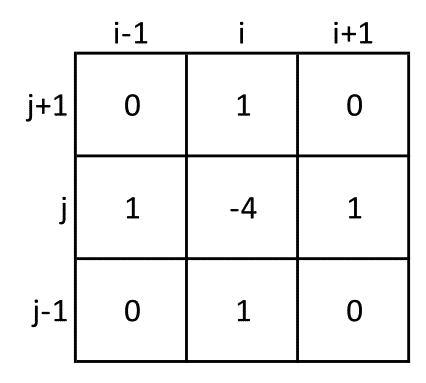

## Paramétrisation

On commence alors par définir les paramètres utiles à notre résolution, à savoir $\mu$, $f$, $\Delta$, $\mathrm{Nx}$ et $\mathrm{Ny}$.

mu=3e6;
f=3e8;
D=0.008;

x=0:D:1;
Nx=length(x)-1;

y=0:D:0.2;
Ny=length(y)-1;

## Implémentation

La manière dont le sytème a été posé implique que la matrice $A$ est creuse et contient $5\mathrm{NxNy}$ coefficients non nuls. En effet, d'après le noyau de Laplace, il y aura 5 coefficients non nul par ligne. Il convient donc d'utiliser la fonction *spalloc* qui optimise la création de matrices creuses. Pour $b_{\mathrm{bords}}$, la fonction *zeros* convient.

NA=Nx*Ny;
A=spalloc(NA,NA,5*NA);
b=zeros(NA,1);

Finalement, il faut construire les matrices $A$ et $b_{\mathrm{bords}}$. Pour cela, on utilise les relations suivantes :


$$k_{i,j+1}=k_{i,j}+1
$$



$$k_{i,j-1}=k_{i,j}-1$$



$$k_{i+1,j}=k_{i,j}+Ny$$



$$k_{i-1,j}=k_{i,j}-Ny$$


for i=1:Nx
    for j=1:Ny
        
        k=(i-1)*Ny+j;
        
        A(k,k)=-4-(f/mu)*D^2; %le noyau de laplace est legerement different car on a homogeneise l'equation (3)
        
        if i==1 || i==Nx
            A(k,k)=1; 
            b(k)=0;
        elseif j==1 || j==Ny
            A(k,k)=1;
            b(k)=sin(3*D*(i-1)*pi)^2;
        else
            A(k,k+1)=1;
            A(k,k-1)=1;
            A(k,k+Ny)=1;
            A(k,k-Ny)=1;
        end
      
    end
end

Il suffit maintenant de résoudre de système et d'utiliser la fonction *reshape* afin de visualiser $g$ sous la forme d'une matrice de $M_{\mathrm{Ny},\mathrm{Nx}} \left(\Re \right)$.

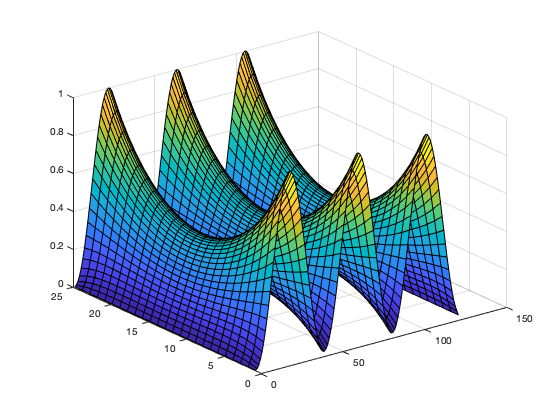

g=A\b;

surf(reshape(g,[Ny,Nx]))